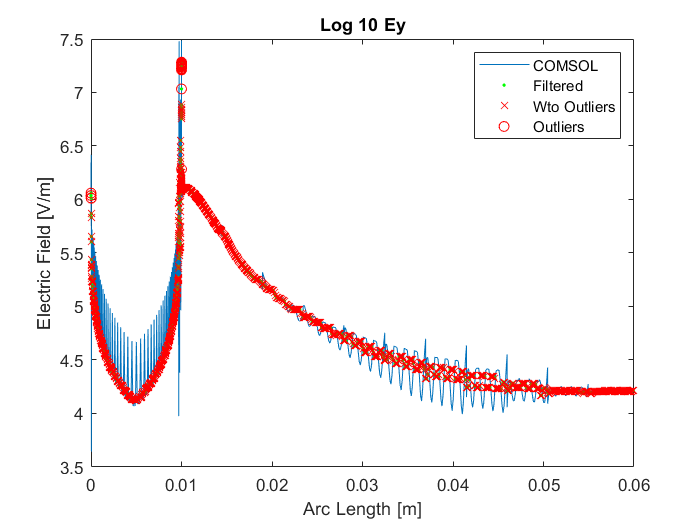

clear;clc;
importey_insulator
% importey_interface
n=length(x); %The whole sheet
x=x(1:round(n/2)); %Half a sheet is good enough
Ey=Ey(1:round(n/2)); %Half a sheet is good enough

log10_ey=log10(abs(Ey));
yMedFilt = medfilt1(log10_ey,17,'truncate');
% semilogy(x,abs(Ey))
[B,ixs] = rmoutliers(yMedFilt,'movmedian',1000); % B- Data wto oujtliers, ixs- outlier indexes; 
figure
plot(x,log10_ey)
hold on
plot(x,yMedFilt,'g.')
hold on

plot(x(~ixs),B,'rx')
plot(x(ixs),yMedFilt(ixs),'ro')
title('Log 10 Ey')
legend({
    'COMSOL',...
    'Filtered',...
    'Wto Outliers',...
    'Outliers'
    })
xlabel('Arc Length [m]')
ylabel('Electric Field [V/m]')

## Gaussian Filter (Seems to work)!

sigma=0.0001;
log10_ey_filt=gaussfilt(x,log10_ey,sigma);

hold off

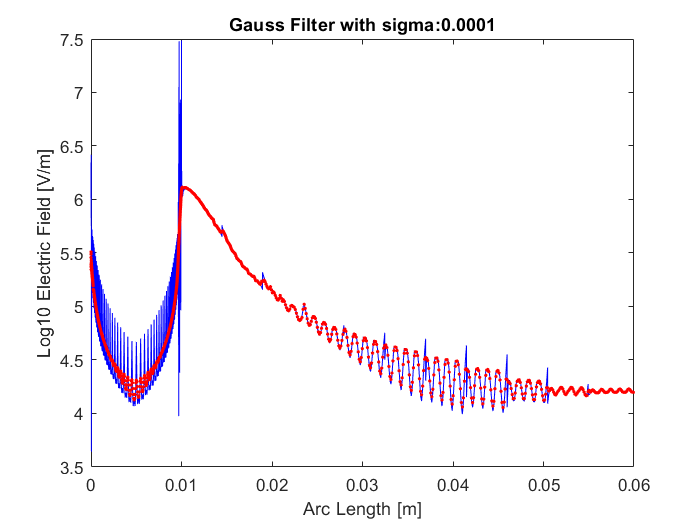

plot(x,log10_ey,'b')
hold on
plot(x,log10_ey_filt,'r.')

title(['Gauss Filter with sigma:',num2str(sigma)])
xlabel('Arc Length [m]')
ylabel('Log10 Electric Field [V/m]')

## Reconstruction of Electric Field

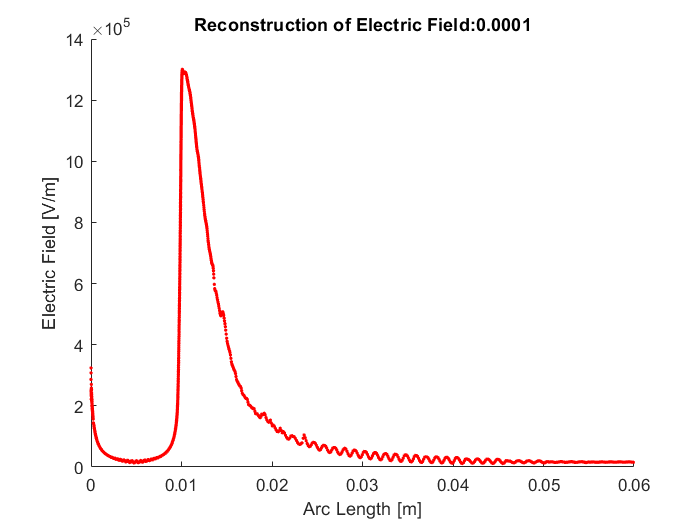

ey_filt=(ones(size(log10_ey_filt))*10).^(log10_ey_filt);
figure()

hold off
% plot(x,Ey,'b')
hold on
plot(x,ey_filt,'r.')

title(['Reconstruction of Electric Field:',num2str(sigma)])
xlabel('Arc Length [m]')
ylabel('Electric Field [V/m]')

## Calculation of Force

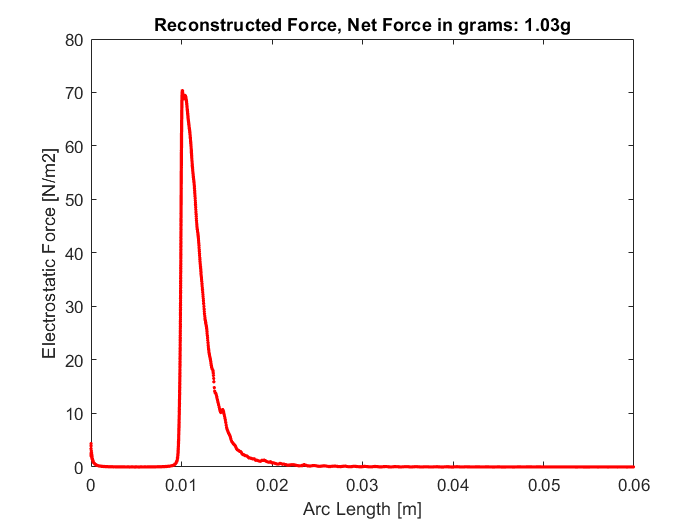

epsilon_0=8.85*10^(-12);
er_oil=2.7;
er_insulator=4.7;
force=ey_filt.^2*epsilon_0*er_insulator;


% Net Force calculation
width=0.0127;
tot_force=trapz(x,force)*width; % N
g_const=9.81;%m/s-2
tot_force_in_grams=1000*tot_force/g_const;

figure
plot(x,force,'r.')

title(['Reconstructed Force, Net Force in grams: ',num2str(round(4*tot_force_in_grams,2)),'g'])
xlabel('Arc Length [m]')
ylabel('Electrostatic Force [N/m2]')